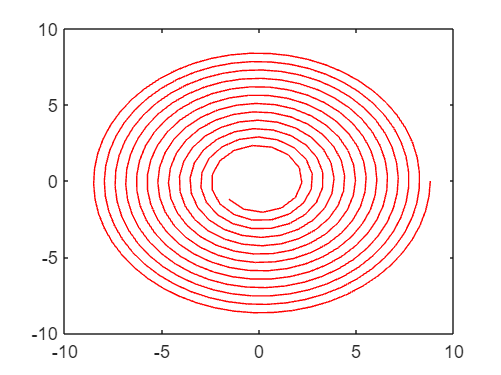

clc;
clear;

a = 8.8;
b = 0.087580;
n = 420;
theta = zeros(1, n);
x = zeros(1, n);
y = zeros(1, n);
r = zeros(1, n);
x(1)=a;
theta(1) = 0; % 初始化第一个 theta

syms theta_s
%计算龙头节点在300s时间内每一秒的坐标
for i=2:420
    f = (-b*(a/b - theta_s)/2)*sqrt(1+(a/b - theta_s)^2) + (1/2)*log(abs((a/b - theta_s)+sqrt(1+(a/b - theta_s)^2))) - (-b*(a/b - theta(i-1))/2)*sqrt(1+(a/b - theta(i-1))^2) - (1/2)*log(abs((a/b - theta(i-1))+sqrt(1+(a/b - theta(i-1))^2))) == 1;
    % 将当前计算得到的 theta(i) 添加到列表中
    sol = vpasolve(f, theta_s);
    theta(i) = sol;
    %极坐标系下的计算
    r_i = a - b*abs(sol);
    r(i) = r_i;

    %直角坐标系下的计算
    x_i = r(i)*cos(sol);
    y_i = r(i)*sin(sol);
    x(i) = x_i;
    y(i) = -y_i;
end
plot(x,y,'r');


%保存数据
writematrix(r,'r1.xlsx');
writematrix(x, 'x1.xlsx');
writematrix(y, 'y1.xlsx');
writematrix(theta,'theta1.xlsx');


